PLOT RIGID BODY TREE WITH TRAJECTORY FROM LOG FILE (floatEVO)

- plotta la traiettoria del joint 6 in modo da plottare tutto il file di log

- con un pin stabilisci inizio e fine della traiettoria da estrarre nel tempo

- per i joints successivi stabilisci lo stesso periodo di tempo

Determina l'intervallo di interesse di tempo per poter plottare le traiettorie della sola resistenza a 3 livelli

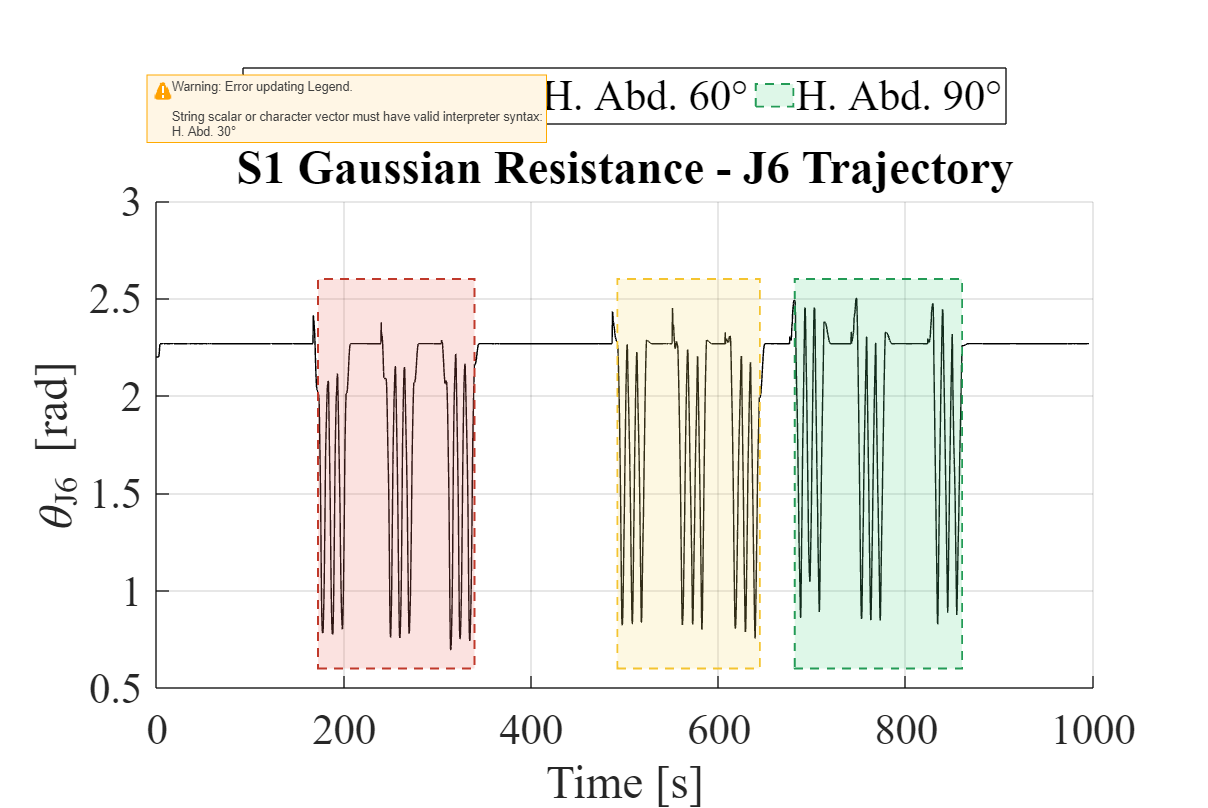

clear all, close all, clc

label_fontsize = 38;
title_fontsize = 42;
tick_fontsize = 34;  % Font size per i numeri degli assi
legend_fontsize = 34; % Font size per la legenda
figure_size = [100, 100, 1600, 1300];   % Dimensioni maggiori per Pectoralis Major

PS = PLOT_STANDARDS();

% Specifica il percorso del file di log
filename = 'Joint6.log';  % Sostituisci con il percorso corretto del file

% Configura le opzioni di importazione
opts = detectImportOptions(filename, 'Delimiter', ' ', 'Whitespace', ' ', 'VariableNamingRule', 'preserve');
opts.DataLines = [2, Inf];  % Inizia a leggere dalla seconda riga per saltare l'intestazione

% Leggi i dati dal file di log
dataJ6 = readtable(filename, opts);
time = dataJ6{:, 1};
J6 = dataJ6{:,2};

% Shiftare il tempo in modo che parta da 0
timeShifted = time - time(1);

% Creare il plot
fig = figure('Name', sprintf('J6Traj_S1'), 'NumberTitle', 'off');
hold on
plot(timeShifted, J6, 'Color', 'k');  % Imposta la larghezza della linea per maggiore visibilità


% Imposta etichette degli assi e il titolo con font "Times"
xlabel('Time [s]', 'FontSize', label_fontsize, 'FontName', 'Times');  
ylabel('\theta_{J6} [rad]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');  
title('S1 Gaussian Resistance - J6 Trajectory', 'FontSize', title_fontsize, 'FontName', 'Times', 'FontWeight', 'bold', 'Interpreter','none'); 

% Definisci gli intervalli di tempo per ciascun livello di resistenza
% Tempo in secondi, con lo shift di tempo aggiunto
t30_start_low = 172.2;
t30_end_low = 202.2;
t30_start_medium = 244.4;
t30_end_medium = 274.4;
t30_start_high = 309.32;
t30_end_high = 339.32;

t60_start_low = 491.88;
t60_end_low = 522.88;
t60_start_medium = 556;
t60_end_medium = 587;
t60_start_high = 613;
t60_end_high = 644;

t90_start_low = 681.26;
t90_end_low = 712.46;
t90_start_medium = 747.44;
t90_end_medium = 778.00;
t90_start_high = 829;
t90_end_high = 860;

%% HABD30
% Riempire lo spazio tra le linee con il colore PS.Red1 e trasparenza
ylimVals = ylim;  % Ottieni i valori attuali dei limiti degli assi y

% Definisci le coordinate per riempire l'area tra le due linee
x_fill = [t30_start_low t30_end_high t30_end_high t30_start_low];
y_fill = [ylimVals(1) ylimVals(1) ylimVals(2) ylimVals(2)];

% Riempi l'area con PS.Red1 con trasparenza
fill(x_fill, y_fill, PS.Red1, 'FaceAlpha', 0.2, 'EdgeColor', PS.DRed2, 'LineWidth', 1.5, 'LineStyle', '--');


%% HABD60
% Definisci le coordinate per riempire l'area tra le due linee
x_fill = [t60_start_low t60_end_high t60_end_high t60_start_low];
y_fill = [ylimVals(1) ylimVals(1) ylimVals(2) ylimVals(2)];

% Riempi l'area con PS.Red1 con trasparenza
fill(x_fill, y_fill, PS.DYellow1, 'FaceAlpha', 0.2, 'EdgeColor', PS.Yellow5, 'LineWidth', 1.5, 'LineStyle', '--');


%% HABD90
% Definisci le coordinate per riempire l'area tra le due linee
x_fill = [t90_start_low t90_end_high t90_end_high t90_start_low];
y_fill = [ylimVals(1) ylimVals(1) ylimVals(2) ylimVals(2)];

% Riempi l'area con PS.Red1 con trasparenza
fill(x_fill, y_fill, PS.LGreen1, 'FaceAlpha', 0.2, 'EdgeColor', PS.LGreen4, 'LineWidth', 1.5, 'LineStyle', '--');


% Usa patch per creare degli oggetti da usare nella legenda
hPatch30 = patch(NaN, NaN, PS.Red1, 'FaceAlpha', 0.2, 'LineStyle', '--', 'Linewidth', 1.5, 'EdgeColor', PS.Red2);   % Oggetto per H. Abd. 30°
hPatch60 = patch(NaN, NaN, PS.DYellow1, 'FaceAlpha', 0.2, 'LineStyle', '--', 'Linewidth', 1.5, 'EdgeColor', PS.Yellow5);  % Oggetto per H. Abd. 60°
hPatch90 = patch(NaN, NaN, PS.LGreen1, 'FaceAlpha', 0.2, 'LineStyle', '--', 'Linewidth', 1.5, 'EdgeColor', PS.LGreen4);  % Oggetto per H. Abd. 90°

% Imposta la dimensione del font dei ticks sugli assi
set(gca, 'FontName', 'Times', 'FontSize', tick_fontsize);

legend([hPatch30, hPatch60, hPatch90], {'H. Abd. 30°', 'H. Abd. 60°', 'H. Abd. 90°'}, 'FontSize', legend_fontsize, ...
    'FontName', 'Times', 'Location', 'northoutside', Orientation='horizontal', Interpreter='latex', Box='on');
set(fig, 'Position', figure_size);

% Aggiungi griglia
grid on;

% Salva la figura in formato SVG
saveas(gcf, 'J6Traj_S1_GaussRes.svg');

hold off;

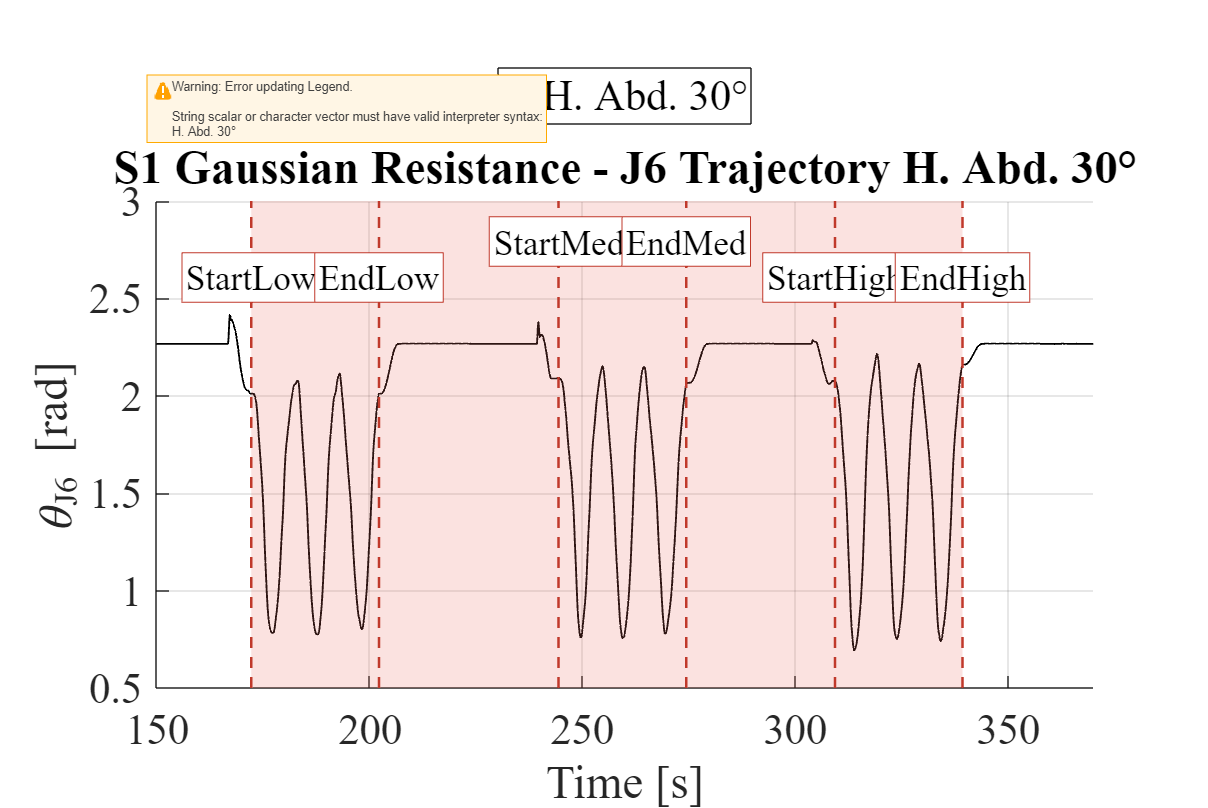

% Creare il plot
fig = figure('Name', sprintf('J6Traj_S1_HAbd30'), 'NumberTitle', 'off');
hold on;
plot(timeShifted, J6, 'Color', 'k', 'LineWidth', 1.5);  % Imposta la larghezza della linea per maggiore visibilità


% Imposta etichette degli assi e il titolo con font "Times"
xlabel('Time [s]', 'FontSize', label_fontsize, 'FontName', 'Times');  
ylabel('\theta_{J6} [rad]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');  
title('S1 Gaussian Resistance - J6 Trajectory H. Abd. 30°', 'FontSize', title_fontsize, 'FontName', 'Times', 'FontWeight', 'bold', 'Interpreter','none'); 

xlim([150 370]);
ylim([0.5 3]);

% Riempire lo spazio tra le linee con il colore PS.Red1 e trasparenza
ylimVals = ylim;  % Ottieni i valori attuali dei limiti degli assi y

% Definisci le coordinate per riempire l'area tra le due linee
x_fill = [t30_start_low t30_end_high t30_end_high t30_start_low];
y_fill = [ylimVals(1) ylimVals(1) ylimVals(2) ylimVals(2)];

%% HABD30
% Riempi l'area con PS.Red1 con trasparenza
fill(x_fill, y_fill, PS.Red1, 'FaceAlpha', 0.2, 'EdgeColor','none');

% Usa patch per creare degli oggetti da usare nella legenda
hPatch30 = patch(NaN, NaN, PS.Red1, 'FaceAlpha', 0.2, 'EdgeColor','none');   % Oggetto per H. Abd. 30°

% Aggiungere linee verticali tratteggiate per i vari intervalli
line([t30_start_low t30_start_low], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);
line([t30_end_low t30_end_low], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);
line([t30_start_medium t30_start_medium], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);
line([t30_end_medium t30_end_medium], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);
line([t30_start_high t30_start_high], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);
line([t30_end_high t30_end_high], ylimVals, 'Color', PS.DRed2, 'LineStyle', '--', 'LineWidth', 2);

% Aggiungere le etichette per i livelli di resistenza
text(t30_start_low, 2.5, 'StartLow', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');
text(t30_end_low, 2.5, 'EndLow', 'HorizontalAlignment', 'center','VerticalAlignment', 'bottom', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');
text(t30_start_medium, 2.9, 'StartMed', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');
text(t30_end_medium, 2.9, 'EndMed', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');
text(t30_start_high, 2.5, 'StartHigh', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');
text(t30_end_high, 2.5, 'EndHigh', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'FontSize', label_fontsize-10, 'FontName', 'Times', 'BackgroundColor', 'w', 'EdgeColor', PS.DRed2, 'Color', 'k');

% Imposta la dimensione del font dei ticks sugli assi
set(gca, 'FontName', 'Times', 'FontSize', tick_fontsize);

legend(hPatch30, 'H. Abd. 30°', 'FontSize', legend_fontsize, ...
    'FontName', 'Times', 'Location', 'northoutside', Orientation='horizontal', Interpreter='latex', Box='on');
set(fig, 'Position', figure_size);

% Aggiungi griglia
grid on;

% Salva la figura in formato SVG
saveas(gcf, 'J6Traj_S1_HABD30.svg');

Load Data Joints

clear all, close all, clc

% Definisci il numero totale di giunti
numJoints = 7;

% Prealloca le celle per i dati
timeData = cell(numJoints, 1);
jointAngles = cell(numJoints, 1);

% Ciclo per leggere i file di log per ciascun giunto
for i = 1:numJoints
    % Costruisci il nome del file di log
    filename = sprintf('Joint%d.log', i);
    
    % Configura le opzioni di importazione
    opts = detectImportOptions(filename, 'Delimiter', ' ', 'Whitespace', ' ', 'VariableNamingRule', 'preserve');
    opts.DataLines = [2, Inf];  % Salta la riga di intestazione
    
    % Leggi i dati dal file di log
    data = readtable(filename, opts);
    
    % Estrai le colonne
    timeData{i} = data{:, 1};
    jointAngles{i} = data{:, 2};
end

% Prendi il tempo da Joint6 per calcolare lo shift
timeShift = timeData{6}(1); % Il primo valore di tempo in Joint6

% Definisci gli intervalli di tempo per ciascun livello di resistenza
% Tempo in secondi, con lo shift di tempo aggiunto
t30_start_low = 172.2 + timeShift;
t30_end_low = 202.2 + timeShift;
t30_start_medium = 244.4 + timeShift;
t30_end_medium = 274.4 + timeShift;
t30_start_high = 309.32 + timeShift;
t30_end_high = 339.32 + timeShift;

% Trova gli indici corrispondenti agli intervalli di tempo
idx_start_low = timeToIndex(timeData{6}, t30_start_low);
idx_end_low = timeToIndex(timeData{6}, t30_end_low);
idx_start_medium = timeToIndex(timeData{6}, t30_start_medium);
idx_end_medium = timeToIndex(timeData{6}, t30_end_medium);
idx_start_high = timeToIndex(timeData{6}, t30_start_high);
idx_end_high = timeToIndex(timeData{6}, t30_end_high);

% Estrai gli angoli dei giunti per ciascun livello di resistenza
anglesLow = extractAngles(jointAngles, idx_start_low, idx_end_low);
anglesMedium = extractAngles(jointAngles, idx_start_medium, idx_end_medium);
anglesHigh = extractAngles(jointAngles, idx_start_high, idx_end_high);

**LOW RESISTANCE  - HABD 30 - S1**

q1tot_Low = anglesLow(:,1);
q2tot_Low = anglesLow(:,2);
q3tot_Low = anglesLow(:,3);
q4tot_Low = anglesLow(:,4);
q5tot_Low = anglesLow(:,5);
q6tot_Low = anglesLow(:,6);
q7tot_Low = anglesLow(:,7);

xLow = zeros(length(q1tot_Low),1);
yLow = zeros(length(q1tot_Low),1);
zLow = zeros(length(q1tot_Low),1);

armL=312.000*1e-3; FarmL=274.000*1e-3-0.07;

i=1;
while(i<length(q1tot_Low))
    qref1=q1tot_Low(i);
    qref2=q2tot_Low(i);
    qref3=q3tot_Low(i);
    qref4=q4tot_Low(i);
    qref5=q5tot_Low(i);
    qref6=q6tot_Low(i);
    qref7=q7tot_Low(i);
    xLow(i)= 0.0555*cos(qref1) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + (0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) - 0.275*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*sin(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) - 1.1e-7*cos(qref5 + 1.69)*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) + 0.0256*sin(qref2 + 1.57)*sin(qref1) - 5.97e-7*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + armL*sin(qref6 - 2.27)*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*cos(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07) - 1.0*armL*cos(qref6 - 2.27)*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + sin(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*(0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07);
    yLow(i)= 0.0555*sin(qref1) + 5.97e-7*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + (0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.275*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + cos(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) + 1.1e-7*cos(qref5 + 1.69)*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) - 0.0256*sin(qref2 + 1.57)*cos(qref1) + 5.97e-7*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) + armL*cos(qref6 - 2.27)*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + armL*sin(qref6 - 2.27)*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07) + 1.0*cos(qref7)*(1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) - (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07);
    zLow(i)= 8.76e-5*cos(qref2 + 1.57) + 0.1*sin(qref2 + 1.57) - 1.1e-7*sin(qref5 + 1.69)*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + 5.97e-7*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 1.1e-7*cos(qref5 + 1.69)*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 0.0872*sin(qref2 + 1.57)*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.996*sin(qref2 + 1.57)*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.274*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.024*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + armL*cos(qref6 - 2.27)*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*armL*sin(qref6 - 2.27)*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + cos(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + 0.0925;

    i=i+1;
end

% Remove any potential first point at the origin
xLow = xLow(xLow ~= 0); 
yLow = yLow(yLow ~= 0); 
zLow = zLow(zLow ~= 0);

**RIGID BODY TREE  -  HABD 30 - S1**

A partire dagli angoli dei giunti estratti, tramite la cinematica diretta, mi sono ricaata la traiettoria percorsa dall'end-effector dell'eso durante le acquisizioni

% Define the rigid body tree
qref=[0; -1.5708; 0; 3.2070; -1.6890; 2.2689; -0.3491]; %rad

Tq1=trotz(-qref1+qref(1));
Tq2=trotz(-qref2+qref(2));
Tq3=trotz(-qref3+qref(3));
Tq4=trotz(-qref4+qref(4));
Tq5=trotz(-qref5+qref(5));
Tq6=trotz(-qref6+qref(6));
Tq7=trotz(-qref7+qref(7));

% Define transformation matrices for DIRECT KINEMATICS (From one frame to the following one))
T01= [1	  0	  0	   0
    0	-1	0	0
    0	0	-1   0
    0    0   0   1];

T12 = Tq1*[0.0000000000	0.0000000000	-1.00000	79.0000*1e-3
    -1.00000	0.0000000000	0.0000000000	0.0000000000*1e-3
    0.0000000000	1.00000	0.0000000000	-92.5000*1e-3
    0 0 0 1];

T23 = Tq2*[0.996195 -0.0871557 0.0000000000 100.000*1e-3;
    0.0000000000 0.0000000000 -1.00000 25.5000*1e-3;
    0.0871557 0.996195 0.0000000000 23.5000*1e-3
    0 0 0 1];

T34 = Tq3*[0.601107 0.693559 -0.397047 -6.59838*1e-3;
    -0.522988 -0.0342784 -0.851651 127.674*1e-3;
    -0.604280 0.719584 0.342118 119.841*1e-3
    0 0 0 1];

T45 = Tq4*[-0.0289212 -0.243626 0.969438 331.548*1e-3;
    0.993027 -0.117884 0.0000000000 0.0000000000;
    0.114281 0.962678 0.245336 -191.595*1e-3
    0 0 0 1];

T56 = Tq5*[-0.302011 0.359923 0.882748 116.964*1e-3;
    -0.766044 -0.642788 0.0000000000 0.0000000000*1e-3;
    0.567420 -0.676224 0.469846 -279.745*1e-3
    0 0 0 1];

T67 = Tq6*[0.939693 -0.342020 0.0000000000 armL;
    0.342020 0.939693 0.0000000000 0.0000000000;
    0.0000000000 0.0000000000 1.00000 0.0000000000;
    0 0 0 1];

T7ee=Tq7*[1.00000	0.0000000000	0.0000000000	FarmL+0.07    %the end effector is 7cm after the brace on the shoulder axis
    0.0000000000	1.00000	0.0000000000	0.0000000000*1e-3
    0.0000000000	0.0000000000	1.00000	-132.500*1e-3
    0 0 0 1];

% RIGID BODY TREE design
FloatEvo = rigidBodyTree;
FloatEvo.Gravity=[0 0 -9.81];
DataFormat='row';

% Joint1: scapular protraction
bodybase= rigidBody('base');
basename = FloatEvo.BaseName;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,T01);
body1.Joint = jnt1;
addBody(FloatEvo,body1,basename)

% Joint2: scapular elevation
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,T12);
body2.Joint = jnt2;
addBody(FloatEvo,body2,'body1')

% Joint3: shoulder complex
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3,T23);
body3.Joint = jnt3;
addBody(FloatEvo,body3,'body2')

% Joint4: shoulder complex
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.PositionLimits=[0, 2*pi];
setFixedTransform(jnt4,T34);
body4.Joint = jnt4;
addBody(FloatEvo,body4,'body3')

% Joint5: shoulder complex
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
setFixedTransform(jnt5,T45);
body5.Joint = jnt5;
addBody(FloatEvo,body5,'body4')

% Joint6: shoulder complex
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
setFixedTransform(jnt6,T56);
body6.Joint = jnt6;
addBody(FloatEvo,body6,'body5')

% Joint7: shoulder complex
body7 = rigidBody('body7');
jnt7 = rigidBodyJoint('jnt7','revolute');
setFixedTransform(jnt7,T67);
body7.Joint = jnt7;
addBody(FloatEvo,body7,'body6')

% End-effector
bodyEndEffector= rigidBody('endeffector');
setFixedTransform(bodyEndEffector.Joint,T7ee);
addBody(FloatEvo,bodyEndEffector,'body7')

SHOW RIGID BODY TREE WITH TRAJECTORY

configuration = homeConfiguration(FloatEvo);  % Get the default configuration

**Gaussian Resistive Torque**

LOW Gaussian Resistance (colormap AUTUMN: dal giallo al rosso)

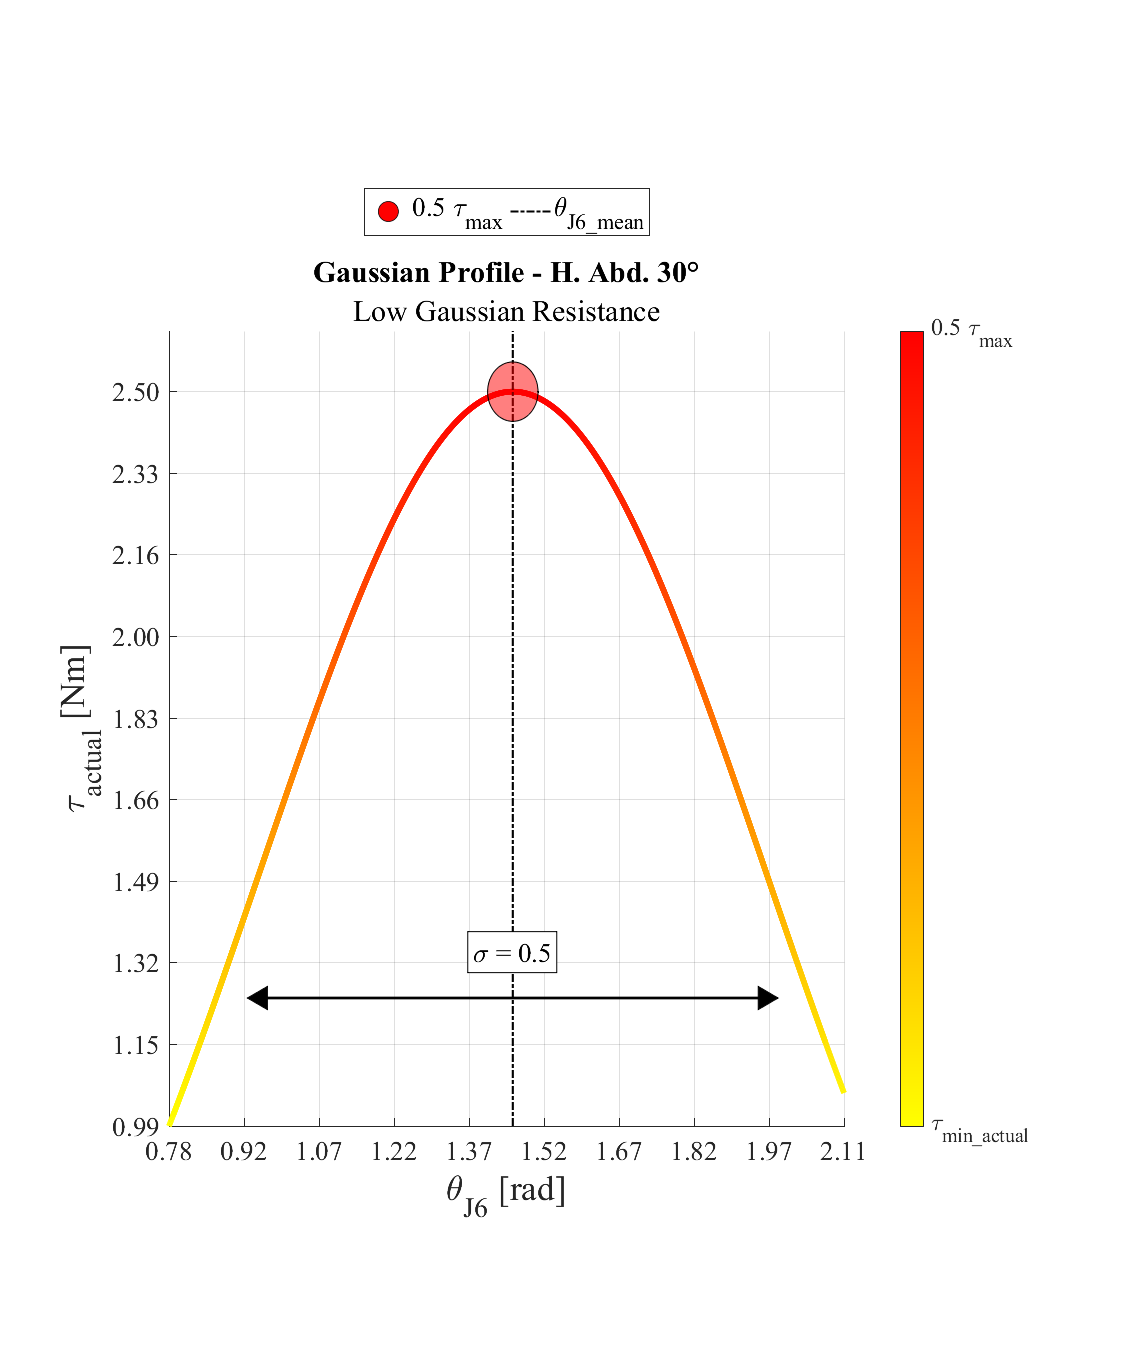

% Gaussian Resistance - parameters
max_torque = 5; % Nm
desired_max_torque = 0.5 * max_torque; % Nm
sigma = 0.5; % rad
minPosJ6 = min(anglesLow(:,6));
maxPosJ6 = max(anglesLow(:,6));
q6_range = [minPosJ6, maxPosJ6]; % rad
mean_shift = 1.457; % rad

% J6 positions in the given interval
q6_values = anglesLow(:,6);

% Needed amplitude to compute the max desired torque as the peak
torqueAmplitude = desired_max_torque / (1/(sigma * sqrt(2 * pi)));

% Resistive Gaussian Torque Profile
resTorque = torqueAmplitude * (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((q6_values - mean_shift) / sigma).^2);

% Find the position and the value of the max Torque
[max_torque, max_index] = max(resTorque);
max_q6 = q6_values(max_index);

% Create a colormap based on the values of resTorque
num_points = length(q6_values);
color_map = flipud(autumn(num_points)); % Inverted color map with autumn colors

% Normalize resTorque between 0 and 1 based on its min and max values
min_resTorque = min(resTorque);
max_resTorque = max(resTorque);
normalized_resTorque = (resTorque - min_resTorque) / (max_resTorque - min_resTorque); % Linear scaling

close all

% Plot Gaussian profile with color gradient
fig = figure('Name', sprintf('Gaussian Profile'), 'NumberTitle', 'off');
fig_size = [100, 100, 900, 1100]; 
fig.Position = fig_size;  
fig.PaperPositionMode = 'auto'; 
set(fig, 'Renderer', 'painters');

hold on;

% Plot with color gradient
for i = 1:num_points-1
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;
    plot(q6_values(i:i+1), resTorque(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 4);
end

% Font size and style settings
label_fontsize = 26;
title_fontsize = 30;
tick_fontsize = 20;  
legend_fontsize = 20;

% Title and axis labels with Times font
title('Gaussian Profile - H. Abd. 30°', 'FontSize', title_fontsize, 'FontName', 'Times', 'FontWeight', 'bold', 'Interpreter','tex');
subtitle('Low Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlim([minPosJ6, maxPosJ6]);
ylim([min_resTorque max_resTorque*1.05]);

% Plot vertical line corresponding to the max resistance position
y_limits = ylim; 
h_line = plot([max_q6, max_q6], y_limits, 'k-.', 'LineWidth', 1.5); % Vertical line

% Circle to highlight the peak value
center_x = max_q6;
center_y = max_torque;
radius = 0.05; % Adjustable radius for circle

% Circle points
theta = linspace(0, 2*pi, 100);
x = radius * cos(theta) + center_x;

% Calculate aspect ratio based on current axes limits
x_range = xlim; % Current x limits
y_range = ylim; % Current y limits
x_length = diff(x_range);
y_length = diff(y_range);

% Calculate the aspect ratio
aspect_ratio = y_length / x_length;

% Adjust y values based on aspect ratio to maintain circular shape
y = radius * sin(theta) * aspect_ratio + center_y; % Adjust y values for circle

% Yellow circle with transparency
h_peak = patch(x, y, 'red', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Adjust the grid with smaller intervals
xticks(linspace(min(q6_values), max(q6_values), 10));
yticks(linspace(min(resTorque), max(resTorque), 10));
grid on;

% Set the colormap
colormap(flipud(autumn)); 

% Create custom legend for the yellow circle
h_circle = plot(nan, nan, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'red', 'MarkerSize', 12);

% Set figure position and size
set(fig, 'Position', fig_size);

% Legend for the circle and the vertical line
legend([h_circle, h_line], '0.5 \tau_{max}', '\theta_{J6\_mean}', 'Location', 'northoutside', ...
    'FontSize', legend_fontsize, 'FontName', 'Times', 'Orientation', 'horizontal', ...
    'Interpreter', 'tex', 'Box', 'on');

% Adjust axes for high readability and make the plot fill more of the figure
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.6]; 

% Reposition and resize the colorbar
cb = colorbar;
cb.Position(1) = ax.Position(1) + ax.Position(3) + 0.05; 
cb.Position(2) = ax.Position(2); 
cb.Position(3) = 0.02; 
cb.Position(4) = ax.Position(4); 

% Set colorbar label font and limits
cb.Label.FontSize = label_fontsize+2;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '0.5 \tau_{max}'}); 

% Set axis ticks format with 2 decimal places
xtickformat('%.2f');
ytickformat('%.2f');

% Adjust axis tick labels for readability
set(gca, 'FontSize', tick_fontsize, 'FontName', 'Times');

% Label axes with larger fonts
xlabel('\theta_{J6} [rad]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');
ylabel('\tau_{actual} [Nm]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');

% Add line with arrows for sigma
sigma_line_y = max_torque / 2;  
sigma_start = mean_shift - sigma;  
sigma_end = mean_shift + sigma;    

% Plot line with arrows (outside of the legend)
h_sigma_line = plot([sigma_start sigma_end], [sigma_line_y sigma_line_y], 'k-', 'LineWidth', 2, 'HandleVisibility', 'off');
h_arrow_left = plot(sigma_start, sigma_line_y, 'k<', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');
h_arrow_right = plot(sigma_end, sigma_line_y, 'k>', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');

% Add text label for sigma
text(mean_shift, sigma_line_y * 1.05, '\sigma = 0.5', 'FontSize', legend_fontsize, 'FontName', 'Times', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'HandleVisibility', 'off');

drawnow;

% Save figure with high resolution
%print(fig, 'LowGaussProfileHabd30.svg', '-dsvg', '-r300'); % Save as SVG with high resolution
saveas(fig, 'LowGaussProfileHabd30.fig');
saveas(fig, 'LowGaussProfileHabd30.jpeg');


hold off;

**Trajectory Low Res - gradient and rigid body tree**

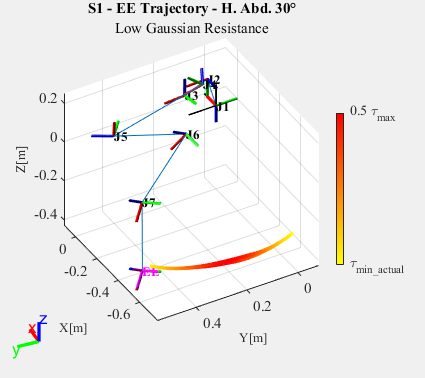

% Calcola il numero di punti basato sulle variabili di posizione
num_points = length(xLow);

% Definisci le dimensioni della figura aumentate per Overleaf (es: 9 cm larghezza per maggiore chiarezza)
figure_width = 9;  % Larghezza in centimetri
figure_height = 8;  % Aumento dell'altezza per evitare che il titolo venga tagliato

% Creazione della figura con dimensioni ottimizzate per Overleaf
fig = figure('Name', sprintf('Gaussian Traj'), 'NumberTitle', 'off', 'Units', 'centimeters', ...
    'Position', [0, 0, figure_width, figure_height]);
hold on;

% Mostra l'albero dei corpi rigidi senza frecce aggiuntive per gli assi
show(FloatEvo);
rotate3d on;
view(3);
grid on;

% Impostare illuminazione per il rendering realistico
light('Position', [1 0 0], 'Style', 'infinite');
light('Position', [0 1 0], 'Style', 'infinite');
light('Position', [0 0 1], 'Style', 'infinite');
lighting phong;  % Phong shading per ombreggiature più morbide
material shiny;  % Materiale lucido per riflessi

% Ottenere i nomi dei corpi dall'albero
bodies = {FloatEvo.BodyNames{1:end}};  % Include la base

% Ciclo per etichettare i corpi senza aggiungere le frecce
for i = 1:numel(bodies)-1  % Escludi l'endeffector per ora
    % Ottenere la trasformazione del sistema di riferimento rispetto alla base
    tform = getTransform(FloatEvo, configuration, bodies{i}, 'base');
    
    % Estrarre la posizione del sistema di riferimento
    position = tform(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione
    
    % Aggiungere l'etichetta "J1", "J2", ..., "J7" con FontName 'Times'
    h_text = text(position(1), position(2), position(3), ['J' num2str(i)], ...
        'FontSize', 8, 'Color', 'k', 'FontWeight', 'bold', 'FontName', 'Times', ...
        'Clipping', 'off');  % Disabilita il clipping per evitare che le etichette siano tagliate
    
    % Porta le etichette in primo piano
    uistack(h_text, 'top');
end

% Ottenere la posizione dell'End-Effector (EE)
tformEE = getTransform(FloatEvo, configuration, 'endeffector', 'base');
positionEE = tformEE(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione

% Aggiungere l'etichetta dell'End-Effector con FontName 'Times'
h_text_EE = text(positionEE(1), positionEE(2), positionEE(3), 'EE', ...
    'FontSize', 8, 'Color', 'm', 'FontWeight', 'bold', 'FontName', 'Times', ...
    'Clipping', 'off');  % Disabilita il clipping per l'etichetta dell'End-Effector
uistack(h_text_EE, 'top');  % Porta l'etichetta dell'end-effector in primo piano

% Plot della traiettoria con gradiente di colore
for i = 1:num_points-1
    % Calcola l'indice del colore in base alla coppia resistiva normalizzata
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;
    
    % Assicurati che l'indice sia valido tra 1 e il numero di punti nella mappa di colori
    color_index = min(max(color_index, 1), size(color_map, 1));
    
    % Plot del segmento della traiettoria con il colore corrispondente
    plot3(xLow(i:i+1), yLow(i:i+1), zLow(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 2);
end

% Impostare i limiti degli assi e il FontName 'Times'
xticks(-0.8:0.2:0.1); % Limiti per l'asse X
yticks(-0.2:0.2:0.8); % Limiti per l'asse Y
zticks(-0.6:0.2:0.5); % Limiti per l'asse Z

% Ruotare il plot di 30° attorno all'asse z
view(-120, 40);  % Angoli di visualizzazione (azimut e elevazione)

% Ottimizzare lo spazio del grafico e impostare il FontName 'Times' per tutti gli elementi
title('S1 - EE Trajectory - H. Abd. 30°', 'FontName', 'Times', 'FontSize', 9); 
subtitle('Low Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlabel('X[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
ylabel('Y[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
zlabel('Z[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');

% Modificare la dimensione e posizione dell'asse per far più spazio alla colorbar
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.75];  % Ulteriore riduzione della larghezza del plot e spostamento a destra

% Gestione del colorbar e dell'asse, con FontName 'Times'
colormap(flipud(autumn));
cb = colorbar;

% Sposta la colorbar in modo che non sia sovrapposta
cb.Position = [0.79, 0.3, 0.02, 0.4];  % Spostamento ancora più a destra della colorbar
cb.Label.FontSize = 8;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '0.5 \tau_{max}'});

% Impostare il FontName degli assi a 'Times'
ax.FontName = 'Times';

% Miglioramenti di smoothing e rendering
set(fig, 'GraphicsSmoothing', 'on');
hold off;

% Salva la figura in formato SVG con dimensioni per Overleaf
print(fig, 'LowGaussResTraj_S1.svg', '-dsvg', '-r300');

% print(fig, 'LowGaussResTraj.jpeg','-djpeg','-r300');
% print(fig, 'LowGaussResTraj.fig', '-dfig', '-r300');
% print(fig, 'GaussLowResTraj_S1.fig');

**MEDIUM RESISTANCE**

q1tot_Medium = anglesMedium(:,1);
q2tot_Medium = anglesMedium(:,2);
q3tot_Medium = anglesMedium(:,3);
q4tot_Medium = anglesMedium(:,4);
q5tot_Medium = anglesMedium(:,5);
q6tot_Medium = anglesMedium(:,6);
q7tot_Medium = anglesMedium(:,7);

xMedium = zeros(length(q1tot_Medium),1);
yMedium = zeros(length(q1tot_Medium),1);
zMedium = zeros(length(q1tot_Medium),1);

i=1;
while(i<length(q1tot_Medium))
    qref1=q1tot_Medium(i);
    qref2=q2tot_Medium(i);
    qref3=q3tot_Medium(i);
    qref4=q4tot_Medium(i);
    qref5=q5tot_Medium(i);
    qref6=q6tot_Medium(i);
    qref7=q7tot_Medium(i);
    xMedium(i)= 0.0555*cos(qref1) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + (0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) - 0.275*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*sin(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) - 1.1e-7*cos(qref5 + 1.69)*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) + 0.0256*sin(qref2 + 1.57)*sin(qref1) - 5.97e-7*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + armL*sin(qref6 - 2.27)*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*cos(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07) - 1.0*armL*cos(qref6 - 2.27)*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + sin(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*(0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07);
    yMedium(i)= 0.0555*sin(qref1) + 5.97e-7*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + (0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.275*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + cos(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) + 1.1e-7*cos(qref5 + 1.69)*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) - 0.0256*sin(qref2 + 1.57)*cos(qref1) + 5.97e-7*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) + armL*cos(qref6 - 2.27)*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + armL*sin(qref6 - 2.27)*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07) + 1.0*cos(qref7)*(1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) - (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07);
    zMedium(i)= 8.76e-5*cos(qref2 + 1.57) + 0.1*sin(qref2 + 1.57) - 1.1e-7*sin(qref5 + 1.69)*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + 5.97e-7*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 1.1e-7*cos(qref5 + 1.69)*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 0.0872*sin(qref2 + 1.57)*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.996*sin(qref2 + 1.57)*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.274*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.024*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + armL*cos(qref6 - 2.27)*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*armL*sin(qref6 - 2.27)*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + cos(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + 0.0925;

    i=i+1;
end

% Remove any potential first point at the origin
xMedium = xMedium(xMedium ~= 0); 
yMedium = yMedium(yMedium ~= 0); 
zMedium = zMedium(zMedium ~= 0);

RIGID BODY TREE  - HABD 30 - S1

% Define the rigid body tree
qref=[0; -1.5708; 0; 3.2070; -1.6890; 2.2689; -0.3491]; %rad

Tq1=trotz(-qref1+qref(1));
Tq2=trotz(-qref2+qref(2));
Tq3=trotz(-qref3+qref(3));
Tq4=trotz(-qref4+qref(4));
Tq5=trotz(-qref5+qref(5));
Tq6=trotz(-qref6+qref(6));
Tq7=trotz(-qref7+qref(7));

% Define transformation matrices for DIRECT KINEMATICS (From one frame to the following one))
T01= [1	  0	  0	   0
    0	-1	0	0
    0	0	-1   0
    0    0   0   1];

T12 = Tq1*[0.0000000000	0.0000000000	-1.00000	79.0000*1e-3
    -1.00000	0.0000000000	0.0000000000	0.0000000000*1e-3
    0.0000000000	1.00000	0.0000000000	-92.5000*1e-3
    0 0 0 1];

T23 = Tq2*[0.996195 -0.0871557 0.0000000000 100.000*1e-3;
    0.0000000000 0.0000000000 -1.00000 25.5000*1e-3;
    0.0871557 0.996195 0.0000000000 23.5000*1e-3
    0 0 0 1];

T34 = Tq3*[0.601107 0.693559 -0.397047 -6.59838*1e-3;
    -0.522988 -0.0342784 -0.851651 127.674*1e-3;
    -0.604280 0.719584 0.342118 119.841*1e-3
    0 0 0 1];

T45 = Tq4*[-0.0289212 -0.243626 0.969438 331.548*1e-3;
    0.993027 -0.117884 0.0000000000 0.0000000000;
    0.114281 0.962678 0.245336 -191.595*1e-3
    0 0 0 1];

T56 = Tq5*[-0.302011 0.359923 0.882748 116.964*1e-3;
    -0.766044 -0.642788 0.0000000000 0.0000000000*1e-3;
    0.567420 -0.676224 0.469846 -279.745*1e-3
    0 0 0 1];

T67 = Tq6*[0.939693 -0.342020 0.0000000000 armL;
    0.342020 0.939693 0.0000000000 0.0000000000;
    0.0000000000 0.0000000000 1.00000 0.0000000000;
    0 0 0 1];

T7ee=Tq7*[1.00000	0.0000000000	0.0000000000	FarmL+0.07    %the end effector is 7cm after the brace on the shoulder axis
    0.0000000000	1.00000	0.0000000000	0.0000000000*1e-3
    0.0000000000	0.0000000000	1.00000	-132.500*1e-3
    0 0 0 1];

% RIGID BODY TREE design
FloatEvo = rigidBodyTree;
FloatEvo.Gravity=[0 0 -9.81];
DataFormat='row';

% Joint1: scapular protraction
bodybase= rigidBody('base');
basename = FloatEvo.BaseName;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,T01);
body1.Joint = jnt1;
addBody(FloatEvo,body1,basename)

% Joint2: scapular elevation
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,T12);
body2.Joint = jnt2;
addBody(FloatEvo,body2,'body1')

% Joint3: shoulder complex
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3,T23);
body3.Joint = jnt3;
addBody(FloatEvo,body3,'body2')

% Joint4: shoulder complex
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.PositionLimits=[0, 2*pi];
setFixedTransform(jnt4,T34);
body4.Joint = jnt4;
addBody(FloatEvo,body4,'body3')

% Joint5: shoulder complex
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
setFixedTransform(jnt5,T45);
body5.Joint = jnt5;
addBody(FloatEvo,body5,'body4')

% Joint6: shoulder complex
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
setFixedTransform(jnt6,T56);
body6.Joint = jnt6;
addBody(FloatEvo,body6,'body5')

% Joint7: shoulder complex
body7 = rigidBody('body7');
jnt7 = rigidBodyJoint('jnt7','revolute');
setFixedTransform(jnt7,T67);
body7.Joint = jnt7;
addBody(FloatEvo,body7,'body6')

% End-effector
bodyEndEffector= rigidBody('endeffector');
setFixedTransform(bodyEndEffector.Joint,T7ee);
addBody(FloatEvo,bodyEndEffector,'body7')
configuration = homeConfiguration(FloatEvo);  % Get the default configuration

MEDIUM Gaussian Resistance (colormap COOL: dal ciano al magenta)

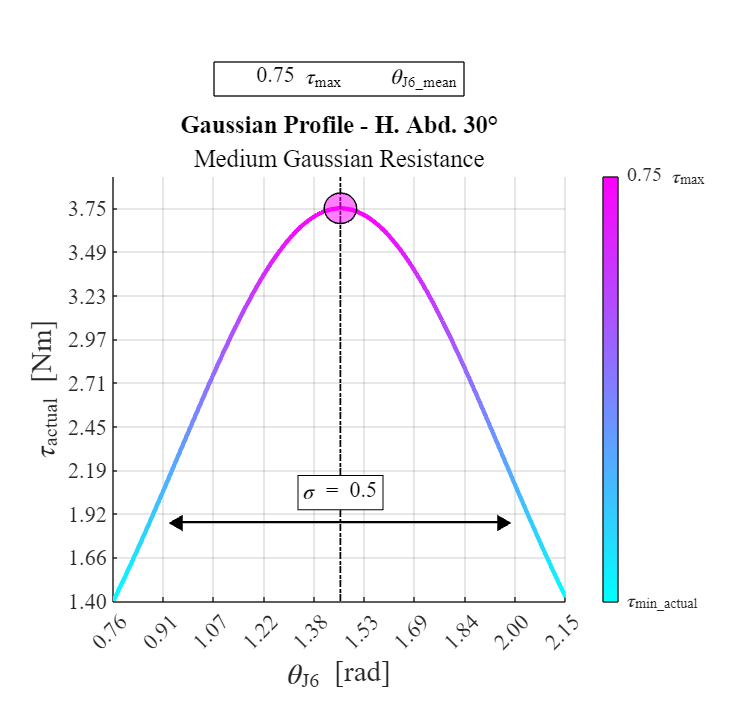

% Gaussian Resistance - parameters
max_torque = 5;
desired_max_torque = 0.75 * max_torque; % Nm
minPosJ6 = min(anglesMedium(:,6));
maxPosJ6 = max(anglesMedium(:,6));
q6_range = [minPosJ6, maxPosJ6]; % rad

% J6 positions in the given interval
q6_values = anglesMedium(:,6);

% Needed amplitude to compute the max desired torque as the peak
% peak value for a Gaussian centered in mean_shift and with st dev sigma
max_pdf_value = (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((mean_shift - mean_shift) / sigma)^2);

% Scale factor to be multiplied to the Gaussian in order to obtain a peak
% exactly where desired (in the standardized distribution it is 1)
torqueAmplitude = desired_max_torque / max_pdf_value;

% Resistive Gaussian Torque Profile
resTorque = torqueAmplitude * (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((q6_values - mean_shift) / sigma).^2);

% Find the position and the value of the max Torque
[max_torque, max_index] = max(resTorque);
max_q6 = q6_values(max_index);

% Create a colormap based on the values of resTorque
num_points = length(q6_values);
color_map = cool(num_points); % Inverted color map with autumn colors

% Normalize resTorque between 0 and 1 based on its min and max values
min_resTorque = min(resTorque);
max_resTorque = max(resTorque);
normalized_resTorque = (resTorque - min_resTorque) / (max_resTorque - min_resTorque); % Linear scaling

close all

% Plot Gaussian profile with color gradient
fig = figure('Name', sprintf('Gaussian Profile'), 'NumberTitle', 'off');
fig_size = [100, 100, 900, 1100]; 
fig.Position = fig_size;  
fig.PaperPositionMode = 'auto'; 
set(fig, 'Renderer', 'painters');

hold on;

% Plot with color gradient
for i = 1:num_points-1
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;
    plot(q6_values(i:i+1), resTorque(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 4);
end

% Font size and style settings
label_fontsize = 26;
title_fontsize = 30;
tick_fontsize = 20;  
legend_fontsize = 20;

% Title and axis labels with Times font
title('Gaussian Profile - H. Abd. 30°', 'FontSize', title_fontsize, 'FontName', 'Times', 'FontWeight', 'bold', 'Interpreter','tex');
subtitle('Medium Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlim([minPosJ6, maxPosJ6]);
ylim([min_resTorque max_resTorque*1.05]);

% Plot vertical line corresponding to the max resistance position
y_limits = ylim; 
h_line = plot([max_q6, max_q6], y_limits, 'k-.', 'LineWidth', 1.5); % Vertical line

% Circle to highlight the peak value
center_x = max_q6;
center_y = max_torque;
radius = 0.05; % Adjustable radius for circle

% Circle points
theta = linspace(0, 2*pi, 100);
x = radius * cos(theta) + center_x;

% Calculate aspect ratio based on current axes limits
x_range = xlim; % Current x limits
y_range = ylim; % Current y limits
x_length = diff(x_range);
y_length = diff(y_range);

% Calculate the aspect ratio
aspect_ratio = y_length / x_length;

% Adjust y values based on aspect ratio to maintain circular shape
y = radius * sin(theta) * aspect_ratio + center_y; % Adjust y values for circle

% Yellow circle with transparency
h_peak = patch(x, y, 'm', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Adjust the grid with smaller intervals
xticks(linspace(min(q6_values), max(q6_values), 10));
yticks(linspace(min(resTorque), max(resTorque), 10));
grid on;

% Set the colormap
colormap(cool); 

% Create custom legend for the yellow circle
h_circle = plot(nan, nan, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'm', 'MarkerSize', 12);

% Set figure position and size
set(fig, 'Position', fig_size);

% Legend for the circle and the vertical line
legend([h_circle, h_line], '0.75 \tau_{max}', '\theta_{J6\_mean}', 'Location', 'northoutside', ...
    'FontSize', legend_fontsize, 'FontName', 'Times', 'Orientation', 'horizontal', ...
    'Interpreter', 'tex', 'Box', 'on');

% Adjust axes for high readability and make the plot fill more of the figure
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.6]; 

% Reposition and resize the colorbar
cb = colorbar;
cb.Position(1) = ax.Position(1) + ax.Position(3) + 0.05; 
cb.Position(2) = ax.Position(2); 
cb.Position(3) = 0.02; 
cb.Position(4) = ax.Position(4); 

% Set colorbar label font and limits
cb.Label.FontSize = label_fontsize+2;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '0.75 \tau_{max}'}); 

% Set axis ticks format with 2 decimal places
xtickformat('%.2f');
ytickformat('%.2f');

% Adjust axis tick labels for readability
set(gca, 'FontSize', tick_fontsize, 'FontName', 'Times');

% Label axes with larger fonts
xlabel('\theta_{J6} [rad]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');
ylabel('\tau_{actual} [Nm]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');

% Add line with arrows for sigma
sigma_line_y = max_torque / 2;  
sigma_start = mean_shift - sigma;  
sigma_end = mean_shift + sigma;    

% Plot line with arrows (outside of the legend)
h_sigma_line = plot([sigma_start sigma_end], [sigma_line_y sigma_line_y], 'k-', 'LineWidth', 2, 'HandleVisibility', 'off');
h_arrow_left = plot(sigma_start, sigma_line_y, 'k<', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');
h_arrow_right = plot(sigma_end, sigma_line_y, 'k>', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');

% Add text label for sigma
text(mean_shift, sigma_line_y * 1.05, '\sigma = 0.5', 'FontSize', legend_fontsize, 'FontName', 'Times', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'HandleVisibility', 'off');

drawnow;

% Save figure with high resolution
print(fig, 'MedGaussProfileHabd30.svg', '-dsvg', '-r300'); % Save as SVG with high resolution
hold off;

Trajectory with gradient and rigid body tree

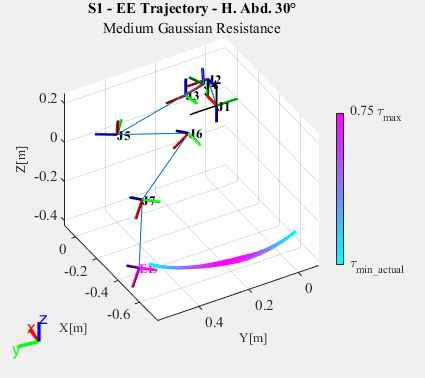

% Adesso 'num_points' sarà calcolato in base alle variabili di posizione
num_points = length(xMedium);

% Definisci le dimensioni della figura aumentate per Overleaf (es: 9 cm larghezza per maggiore chiarezza)
figure_width = 9;  % Larghezza in centimetri
figure_height = 8;  % Aumento dell'altezza per evitare che il titolo venga tagliato

% Creazione della figura con dimensioni ottimizzate per Overleaf
fig = figure('Name', sprintf('Gaussian Traj'), 'NumberTitle', 'off', 'Units', 'centimeters', ...
    'Position', [0, 0, figure_width, figure_height]);
hold on;

% Mostra l'albero dei corpi rigidi senza frecce aggiuntive per gli assi
show(FloatEvo);
rotate3d on;
view(3);
grid on;

% Impostare illuminazione per il rendering realistico
light('Position', [1 0 0], 'Style', 'infinite');
light('Position', [0 1 0], 'Style', 'infinite');
light('Position', [0 0 1], 'Style', 'infinite');
lighting phong;  % Phong shading per ombreggiature più morbide
material shiny;  % Materiale lucido per riflessi

% Ottenere i nomi dei corpi dall'albero
bodies = {FloatEvo.BodyNames{1:end}};  % Include la base

% Ciclo per etichettare i corpi senza aggiungere le frecce
for i = 1:numel(bodies)-1  % Escludi l'endeffector per ora
    % Ottenere la trasformazione del sistema di riferimento rispetto alla base
    tform = getTransform(FloatEvo, configuration, bodies{i}, 'base');
    
    % Estrarre la posizione del sistema di riferimento
    position = tform(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione
    
    % Aggiungere l'etichetta "J1", "J2", ..., "J7" con FontName 'Times'
    h_text = text(position(1), position(2), position(3), ['J' num2str(i)], ...
        'FontSize', 8, 'Color', 'k', 'FontWeight', 'bold', 'FontName', 'Times', ...
        'Clipping', 'off');  % Disabilita il clipping per evitare che le etichette siano tagliate
    
    % Porta le etichette in primo piano
    uistack(h_text, 'top');
end

% Ottenere la posizione dell'End-Effector (EE)
tformEE = getTransform(FloatEvo, configuration, 'endeffector', 'base');
positionEE = tformEE(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione

% Aggiungere l'etichetta dell'End-Effector con FontName 'Times'
h_text_EE = text(positionEE(1), positionEE(2), positionEE(3), 'EE', ...
    'FontSize', 8, 'Color', 'm', 'FontWeight', 'bold', 'FontName', 'Times', ...
    'Clipping', 'off');  % Disabilita il clipping per l'etichetta dell'End-Effector
uistack(h_text_EE, 'top');  % Porta l'etichetta dell'end-effector in primo piano

% Plot della traiettoria con gradiente di colore
for i = 1:(num_points - 1)
    % Calcola l'indice del colore in base alla coppia resistiva normalizzata
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;

    % Assicurati che l'indice sia valido tra 1 e il numero di punti nella mappa di colori
    color_index = min(max(color_index, 1), size(color_map, 1));

    % Plot del segmento della traiettoria con il colore corrispondente
    plot3(xMedium(i:i+1), yMedium(i:i+1), zMedium(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 2);
end

% Impostare i limiti degli assi e il FontName 'Times'
xticks(-0.8:0.2:0.1); % Limiti per l'asse X
yticks(-0.2:0.2:0.8); % Limiti per l'asse Y
zticks(-0.6:0.2:0.5); % Limiti per l'asse Z

% Ruotare il plot di 30° attorno all'asse z
view(-120, 40);  % Angoli di visualizzazione (azimut e elevazione)

% Ottimizzare lo spazio del grafico e impostare il FontName 'Times' per tutti gli elementi
title('S1 - EE Trajectory - H. Abd. 30°', 'FontName', 'Times', 'FontSize', 9); 
subtitle('Medium Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlabel('X[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
ylabel('Y[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
zlabel('Z[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');

% Modificare la dimensione e posizione dell'asse per far più spazio alla colorbar
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.75];  % Ulteriore riduzione della larghezza del plot e spostamento a destra

% Gestione del colorbar e dell'asse, con FontName 'Times'
colormap(cool);
cb = colorbar;

% Sposta la colorbar in modo che non sia sovrapposta
cb.Position = [0.79, 0.3, 0.02, 0.4];  % Spostamento ancora più a destra della colorbar
cb.Label.FontSize = 8;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '0.75 \tau_{max}'});

% Impostare il FontName degli assi a 'Times'
ax.FontName = 'Times';

% Miglioramenti di smoothing e rendering
set(fig, 'GraphicsSmoothing', 'on');
hold off;

% Salva la figura in formato SVG con dimensioni per Overleaf
print(fig, 'MedGaussResTraj_S1.svg', '-dsvg', '-r300');

**HIGH RESISTANCE**

q1tot_High = anglesHigh(:,1);
q2tot_High = anglesHigh(:,2);
q3tot_High = anglesHigh(:,3);
q4tot_High = anglesHigh(:,4);
q5tot_High = anglesHigh(:,5);
q6tot_High = anglesHigh(:,6);
q7tot_High = anglesHigh(:,7);

xHigh = zeros(length(q1tot_High),1);
yHigh = zeros(length(q1tot_High),1);
zHigh = zeros(length(q1tot_High),1);

i=1;
while(i<length(q1tot_High))
    qref1=q1tot_High(i);
    qref2=q2tot_High(i);
    qref3=q3tot_High(i);
    qref4=q4tot_High(i);
    qref5=q5tot_High(i);
    qref6=q6tot_High(i);
    qref7=q7tot_High(i);
    xHigh(i)= 0.0555*cos(qref1) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + (0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) - 0.275*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*sin(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) - 1.1e-7*cos(qref5 + 1.69)*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) + 0.0256*sin(qref2 + 1.57)*sin(qref1) - 5.97e-7*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + armL*sin(qref6 - 2.27)*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*cos(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07) - 1.0*armL*cos(qref6 - 2.27)*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) + sin(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.166*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 1.0*(0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.656*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.166*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) + 0.0568*sin(qref2 + 1.57)*sin(qref1) - 0.656*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))) - 1.0*(0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.55*sin(qref4 - 3.21)*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + (0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.114*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.114*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.0391*sin(qref2 + 1.57)*sin(qref1)) - 0.139*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.139*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1)) - 1.0*(0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) - 1.0*(0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) + 0.72*sin(qref2 + 1.57)*sin(qref1)) + 0.329*sin(qref2 + 1.57)*sin(qref1)) - 0.0476*sin(qref2 + 1.57)*sin(qref1) + 0.55*cos(qref4 - 3.21)*((0.0872*cos(qref1) + 0.996*cos(qref2 + 1.57)*sin(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) - 1.0*(0.996*cos(qref1) - 0.0872*cos(qref2 + 1.57)*sin(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) + 0.604*sin(qref2 + 1.57)*sin(qref1))))*(FarmL + 0.07);
    yHigh(i)= 0.0555*sin(qref1) + 5.97e-7*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + (0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.275*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.275*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + cos(qref1)*(0.1*cos(qref2 + 1.57) + 0.0255*sin(qref2 + 1.57)) + 1.1e-7*cos(qref5 + 1.69)*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) - 0.0256*sin(qref2 + 1.57)*cos(qref1) + 5.97e-7*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + 1.1e-7*sin(qref5 + 1.69)*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) + armL*cos(qref6 - 2.27)*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + armL*sin(qref6 - 2.27)*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) + (0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07) + 1.0*cos(qref7)*(1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*((0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.55*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.139*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.139*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0476*sin(qref2 + 1.57)*cos(qref1) + 0.55*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))) - (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*((0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*((0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) - 0.114*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 0.114*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.0391*sin(qref2 + 1.57)*cos(qref1)) + 0.656*sin(qref4 - 3.21)*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) + 0.166*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.166*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*(0.963*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.963*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.852*cos(qref3) - 0.397*sin(qref3)) - 1.0*(0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1)) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*((0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.694*cos(qref3) - 0.0343*sin(qref3)) - 1.0*(0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.72*sin(qref2 + 1.57)*cos(qref1)) - 0.329*sin(qref2 + 1.57)*cos(qref1)) - 0.0568*sin(qref2 + 1.57)*cos(qref1) + 0.656*cos(qref4 - 3.21)*((0.996*sin(qref1) + 0.0872*cos(qref2 + 1.57)*cos(qref1))*(0.523*cos(qref3) + 0.601*sin(qref3)) - 1.0*(0.0872*sin(qref1) - 0.996*cos(qref2 + 1.57)*cos(qref1))*(0.601*cos(qref3) - 0.523*sin(qref3)) + 0.604*sin(qref2 + 1.57)*cos(qref1))))*(FarmL + 0.07);
    zHigh(i)= 8.76e-5*cos(qref2 + 1.57) + 0.1*sin(qref2 + 1.57) - 1.1e-7*sin(qref5 + 1.69)*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + 5.97e-7*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 1.1e-7*cos(qref5 + 1.69)*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 0.0872*sin(qref2 + 1.57)*(0.128*cos(qref3) + 0.0066*sin(qref3)) - 0.996*sin(qref2 + 1.57)*(0.0066*cos(qref3) - 0.128*sin(qref3)) - 5.97e-7*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.274*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.024*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + armL*cos(qref6 - 2.27)*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*armL*sin(qref6 - 2.27)*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + cos(qref7)*((0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) + (0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + sin(qref7)*((0.342*cos(qref6 - 2.27) - 0.94*sin(qref6 - 2.27))*(0.0476*cos(qref2 + 1.57) + 0.55*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.55*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.139*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.0121*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.766*cos(qref5 + 1.69) - 0.302*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) - 1.0*(0.302*cos(qref5 + 1.69) + 0.766*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))) - 1.0*(0.94*cos(qref6 - 2.27) + 0.342*sin(qref6 - 2.27))*(0.656*sin(qref4 - 3.21)*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.656*cos(qref4 - 3.21)*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.0568*cos(qref2 + 1.57) + 0.165*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0145*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)) + (0.643*cos(qref5 + 1.69) + 0.36*sin(qref5 + 1.69))*((0.244*cos(qref4 - 3.21) + 0.118*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) - 0.329*cos(qref2 + 1.57) + (0.118*cos(qref4 - 3.21) - 0.244*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) + 0.959*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) - 0.0839*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3))) + (0.36*cos(qref5 + 1.69) - 0.643*sin(qref5 + 1.69))*(0.0391*cos(qref2 + 1.57) - 1.0*(0.0289*cos(qref4 - 3.21) - 0.993*sin(qref4 - 3.21))*(0.0872*sin(qref2 + 1.57)*(0.523*cos(qref3) + 0.601*sin(qref3)) - 0.604*cos(qref2 + 1.57) + 0.996*sin(qref2 + 1.57)*(0.601*cos(qref3) - 0.523*sin(qref3))) + (0.993*cos(qref4 - 3.21) + 0.0289*sin(qref4 - 3.21))*(0.72*cos(qref2 + 1.57) + 0.0872*sin(qref2 + 1.57)*(0.0343*cos(qref3) + 0.694*sin(qref3)) + 0.996*sin(qref2 + 1.57)*(0.694*cos(qref3) - 0.0343*sin(qref3))) - 0.114*sin(qref2 + 1.57)*(0.397*cos(qref3) + 0.852*sin(qref3)) + 0.00996*sin(qref2 + 1.57)*(0.852*cos(qref3) - 0.397*sin(qref3)))))*(FarmL + 0.07) + 0.0925;

    i=i+1;
end

% Remove any potential first point at the origin
xHigh = xHigh(xHigh ~= 0); 
yHigh = yHigh(yHigh ~= 0); 
zHigh = zHigh(zHigh ~= 0);


RIGID BODY TREE  - HABD 30 - S1

% Define the rigid body tree
qref=[0; -1.5708; 0; 3.2070; -1.6890; 2.2689; -0.3491]; %rad

Tq1=trotz(-qref1+qref(1));
Tq2=trotz(-qref2+qref(2));
Tq3=trotz(-qref3+qref(3));
Tq4=trotz(-qref4+qref(4));
Tq5=trotz(-qref5+qref(5));
Tq6=trotz(-qref6+qref(6));
Tq7=trotz(-qref7+qref(7));

% Define transformation matrices for DIRECT KINEMATICS (From one frame to the following one))
T01= [1	  0	  0	   0
    0	-1	0	0
    0	0	-1   0
    0    0   0   1];

T12 = Tq1*[0.0000000000	0.0000000000	-1.00000	79.0000*1e-3
    -1.00000	0.0000000000	0.0000000000	0.0000000000*1e-3
    0.0000000000	1.00000	0.0000000000	-92.5000*1e-3
    0 0 0 1];

T23 = Tq2*[0.996195 -0.0871557 0.0000000000 100.000*1e-3;
    0.0000000000 0.0000000000 -1.00000 25.5000*1e-3;
    0.0871557 0.996195 0.0000000000 23.5000*1e-3
    0 0 0 1];

T34 = Tq3*[0.601107 0.693559 -0.397047 -6.59838*1e-3;
    -0.522988 -0.0342784 -0.851651 127.674*1e-3;
    -0.604280 0.719584 0.342118 119.841*1e-3
    0 0 0 1];

T45 = Tq4*[-0.0289212 -0.243626 0.969438 331.548*1e-3;
    0.993027 -0.117884 0.0000000000 0.0000000000;
    0.114281 0.962678 0.245336 -191.595*1e-3
    0 0 0 1];

T56 = Tq5*[-0.302011 0.359923 0.882748 116.964*1e-3;
    -0.766044 -0.642788 0.0000000000 0.0000000000*1e-3;
    0.567420 -0.676224 0.469846 -279.745*1e-3
    0 0 0 1];

T67 = Tq6*[0.939693 -0.342020 0.0000000000 armL;
    0.342020 0.939693 0.0000000000 0.0000000000;
    0.0000000000 0.0000000000 1.00000 0.0000000000;
    0 0 0 1];

T7ee=Tq7*[1.00000	0.0000000000	0.0000000000	FarmL+0.07    %the end effector is 7cm after the brace on the shoulder axis
    0.0000000000	1.00000	0.0000000000	0.0000000000*1e-3
    0.0000000000	0.0000000000	1.00000	-132.500*1e-3
    0 0 0 1];

% RIGID BODY TREE design
FloatEvo = rigidBodyTree;
FloatEvo.Gravity=[0 0 -9.81];
DataFormat='row';

% Joint1: scapular protraction
bodybase= rigidBody('base');
basename = FloatEvo.BaseName;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,T01);
body1.Joint = jnt1;
addBody(FloatEvo,body1,basename)

% Joint2: scapular elevation
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,T12);
body2.Joint = jnt2;
addBody(FloatEvo,body2,'body1')

% Joint3: shoulder complex
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
setFixedTransform(jnt3,T23);
body3.Joint = jnt3;
addBody(FloatEvo,body3,'body2')

% Joint4: shoulder complex
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt4.PositionLimits=[0, 2*pi];
setFixedTransform(jnt4,T34);
body4.Joint = jnt4;
addBody(FloatEvo,body4,'body3')

% Joint5: shoulder complex
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
setFixedTransform(jnt5,T45);
body5.Joint = jnt5;
addBody(FloatEvo,body5,'body4')

% Joint6: shoulder complex
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');
setFixedTransform(jnt6,T56);
body6.Joint = jnt6;
addBody(FloatEvo,body6,'body5')

% Joint7: shoulder complex
body7 = rigidBody('body7');
jnt7 = rigidBodyJoint('jnt7','revolute');
setFixedTransform(jnt7,T67);
body7.Joint = jnt7;
addBody(FloatEvo,body7,'body6')

% End-effector
bodyEndEffector= rigidBody('endeffector');
setFixedTransform(bodyEndEffector.Joint,T7ee);
addBody(FloatEvo,bodyEndEffector,'body7')

configuration = homeConfiguration(FloatEvo);  % Get the default configuration

HIGH Gaussian Resistance (colormap WINTER: dal verde al blu)

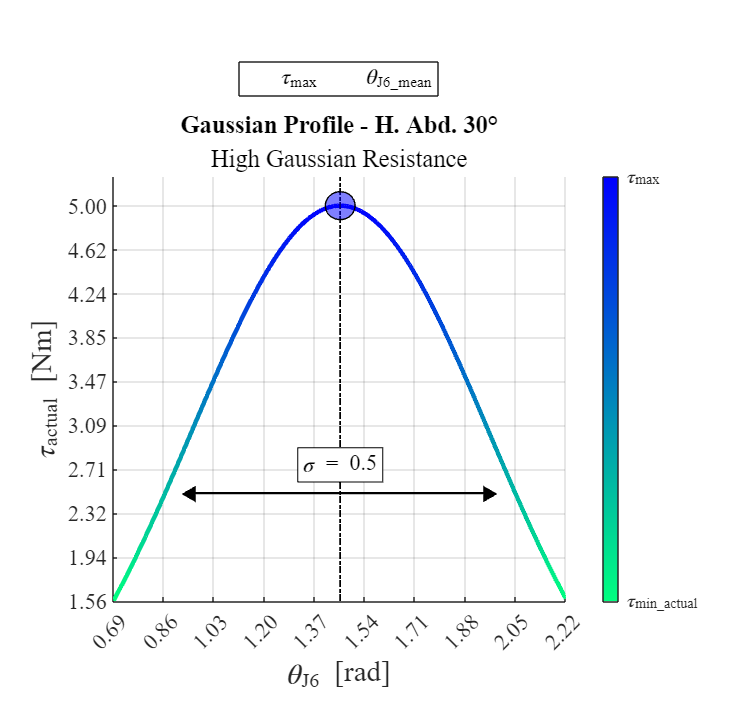

% Gaussian Resistance - parameters
max_torque = 5;
desired_max_torque = 1 * max_torque; % Nm
minPosJ6 = min(anglesHigh(:,6));
maxPosJ6 = max(anglesHigh(:,6));
q6_range = [minPosJ6, maxPosJ6]; % rad

% J6 positions in the given interval
q6_values = anglesHigh(:,6);

% Needed amplitude to compute the max desired torque as the peak
% peak value for a Gaussian centered in mean_shift and with st dev sigma
max_pdf_value = (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((mean_shift - mean_shift) / sigma)^2);

% Scale factor to be multiplied to the Gaussian in order to obtain a peak
% exactly where desired (in the standardized distribution it is 1)
torqueAmplitude = desired_max_torque / max_pdf_value;

% Resistive Gaussian Torque Profile
resTorque = torqueAmplitude * (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((q6_values - mean_shift) / sigma).^2);

% Find the position and the value of the max Torque
[max_torque, max_index] = max(resTorque);
max_q6 = q6_values(max_index);

% Create a colormap based on the values of resTorque
num_points = length(q6_values);
color_map = flipud(winter(num_points)); 

% Normalize resTorque between 0 and 1 based on its min and max values
min_resTorque = min(resTorque);
max_resTorque = max(resTorque);
normalized_resTorque = (resTorque - min_resTorque) / (max_resTorque - min_resTorque); % Now linear scaling between 0 and 1

close all

% Plot Gaussian profile with color gradient
fig = figure('Name', sprintf('Gaussian Profile'), 'NumberTitle', 'off');
fig_size = [100, 100, 900, 1100]; 
fig.Position = [100, 100, 900, 1100];  % Further reduced width and increased height
fig.PaperPositionMode = 'auto'; 
set(fig, 'Renderer', 'painters');

hold on;

% Plot with color gradient
for i = 1:num_points-1
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;
    plot(q6_values(i:i+1), resTorque(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 4);
end

% Font size and style settings
label_fontsize = 26;
title_fontsize = 30;
tick_fontsize = 20;  % Increased axis ticks font size for better visibility
legend_fontsize = 20;

% Title and axis labels with Times font
title('Gaussian Profile - H. Abd. 30°', 'FontSize', title_fontsize, 'FontName', 'Times', 'FontWeight', 'bold', 'Interpreter','tex');
subtitle('High Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlim([minPosJ6, maxPosJ6]);
ylim([min_resTorque max_resTorque*1.05]);

% Plot vertical line corresponding to the max resistance position
y_limits = ylim; 
h_line = plot([max_q6, max_q6], y_limits, 'k-.', 'LineWidth', 1.5); % Vertical line

% Circle to highlight the peak value
center_x = max_q6;
center_y = max_torque;
radius = 0.05; % Adjustable radius for circle

% Circle points
theta = linspace(0, 2*pi, 100);
x = radius * cos(theta) + center_x;

% Calculate aspect ratio based on current axes limits
x_range = xlim; % Current x limits
y_range = ylim; % Current y limits
x_length = diff(x_range);
y_length = diff(y_range);

% Calculate the aspect ratio
aspect_ratio = y_length / x_length;

% Adjust y values based on aspect ratio to maintain circular shape
y = radius * sin(theta) * aspect_ratio + center_y; % Adjust y values for circle

% Yellow circle with transparency
h_peak = patch(x, y, 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'k');

% Adjust the grid with smaller intervals
xticks(linspace(min(q6_values), max(q6_values), 10));
yticks(linspace(min(resTorque), max(resTorque), 10));
grid on;

% Set the colormap
colormap(flipud(winter)); 

% Create custom legend for the yellow circle
h_circle = plot(nan, nan, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b', 'MarkerSize', 12);

% Set figure position and size
set(fig, 'Position', fig_size);

% Legend for the circle and the vertical line
legend([h_circle, h_line], '\tau_{max}', '\theta_{J6\_mean}', 'Location', 'northoutside', ...
    'FontSize', legend_fontsize, 'FontName', 'Times', 'Orientation', 'horizontal', ...
    'Interpreter', 'tex', 'Box', 'on');

% Adjust axes for high readability and make the plot fill more of the figure
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.6]; 

% Reposition and resize the colorbar
cb = colorbar;
cb.Position(1) = ax.Position(1) + ax.Position(3) + 0.05; 
cb.Position(2) = ax.Position(2); 
cb.Position(3) = 0.02; 
cb.Position(4) = ax.Position(4); 

% Set colorbar label font and limits
cb.Label.FontSize = label_fontsize+2;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '\tau_{max}'}); 

% Set axis ticks format with 2 decimal places
xtickformat('%.2f');
ytickformat('%.2f');

% Adjust axis tick labels for readability
set(gca, 'FontSize', tick_fontsize, 'FontName', 'Times');

% Label axes with larger fonts
xlabel('\theta_{J6} [rad]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');
ylabel('\tau_{actual} [Nm]', 'FontSize', label_fontsize, 'FontName', 'Times', 'Interpreter','tex');

% Add line with arrows for sigma
sigma_line_y = max_torque / 2;  
sigma_start = mean_shift - sigma;  
sigma_end = mean_shift + sigma;    

% Plot line with arrows (outside of the legend)
h_sigma_line = plot([sigma_start sigma_end], [sigma_line_y sigma_line_y], 'k-', 'LineWidth', 2, 'HandleVisibility', 'off');
h_arrow_left = plot(sigma_start, sigma_line_y, 'k<', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');
h_arrow_right = plot(sigma_end, sigma_line_y, 'k>', 'MarkerFaceColor', 'k', 'MarkerSize', 12, 'HandleVisibility', 'off');

% Add text label for sigma
text(mean_shift, sigma_line_y * 1.05, '\sigma = 0.5', 'FontSize', legend_fontsize, 'FontName', 'Times', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
    'BackgroundColor', 'w', 'EdgeColor', 'k', 'HandleVisibility', 'off');

drawnow;

% Save figure with high resolution
print(fig, 'HighGaussProfileHabd30.svg', '-dsvg', '-r300'); % Save as SVG with high resolution
hold off;

Trajectory with gradient and rigid body tree

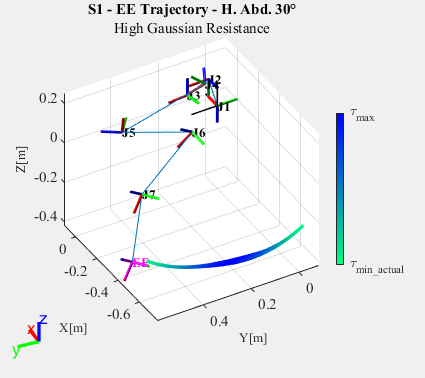

% Adesso 'num_points' sarà calcolato in base alle variabili di posizione
num_points = length(xHigh);

% Definisci le dimensioni della figura aumentate per Overleaf (es: 9 cm larghezza per maggiore chiarezza)
figure_width = 9;  % Larghezza in centimetri
figure_height = 8;  % Aumento dell'altezza per evitare che il titolo venga tagliato

% Creazione della figura con dimensioni ottimizzate per Overleaf
fig = figure('Name', sprintf('Gaussian Traj'), 'NumberTitle', 'off', 'Units', 'centimeters', ...
    'Position', [0, 0, figure_width, figure_height]);
hold on;

% Mostra l'albero dei corpi rigidi senza frecce aggiuntive per gli assi
show(FloatEvo);
rotate3d on;
view(3);
grid on;

% Impostare illuminazione per il rendering realistico
light('Position', [1 0 0], 'Style', 'infinite');
light('Position', [0 1 0], 'Style', 'infinite');
light('Position', [0 0 1], 'Style', 'infinite');
lighting phong;  % Phong shading per ombreggiature più morbide
material shiny;  % Materiale lucido per riflessi

% Ottenere i nomi dei corpi dall'albero
bodies = {FloatEvo.BodyNames{1:end}};  % Include la base

% Ciclo per etichettare i corpi senza aggiungere le frecce
for i = 1:numel(bodies)-1  % Escludi l'endeffector per ora
    % Ottenere la trasformazione del sistema di riferimento rispetto alla base
    tform = getTransform(FloatEvo, configuration, bodies{i}, 'base');
    
    % Estrarre la posizione del sistema di riferimento
    position = tform(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione
    
    % Aggiungere l'etichetta "J1", "J2", ..., "J7" con FontName 'Times'
    h_text = text(position(1), position(2), position(3), ['J' num2str(i)], ...
        'FontSize', 8, 'Color', 'k', 'FontWeight', 'bold', 'FontName', 'Times', ...
        'Clipping', 'off');  % Disabilita il clipping per evitare che le etichette siano tagliate
    
    % Porta le etichette in primo piano
    uistack(h_text, 'top');
end

% Ottenere la posizione dell'End-Effector (EE)
tformEE = getTransform(FloatEvo, configuration, 'endeffector', 'base');
positionEE = tformEE(1:3, 4);  % La posizione è nella quarta colonna della matrice di trasformazione

% Aggiungere l'etichetta dell'End-Effector con FontName 'Times'
h_text_EE = text(positionEE(1), positionEE(2), positionEE(3), 'EE', ...
    'FontSize', 8, 'Color', 'm', 'FontWeight', 'bold', 'FontName', 'Times', ...
    'Clipping', 'off');  % Disabilita il clipping per l'etichetta dell'End-Effector
uistack(h_text_EE, 'top');  % Porta l'etichetta dell'end-effector in primo piano

% Plot della traiettoria con gradiente di colore
for i = 1:(num_points - 1)
    % Calcola l'indice del colore in base alla coppia resistiva normalizzata
    color_index = round(normalized_resTorque(i) * (size(color_map, 1) - 1)) + 1;

    % Assicurati che l'indice sia valido tra 1 e il numero di punti nella mappa di colori
    color_index = min(max(color_index, 1), size(color_map, 1));

    % Plot del segmento della traiettoria con il colore corrispondente
    plot3(xHigh(i:i+1), yHigh(i:i+1), zHigh(i:i+1), 'Color', color_map(color_index, :), 'LineWidth', 2);
end

% Impostare i limiti degli assi e il FontName 'Times'
xticks(-0.8:0.2:0.1); % Limiti per l'asse X
yticks(-0.2:0.2:0.8); % Limiti per l'asse Y
zticks(-0.6:0.2:0.5); % Limiti per l'asse Z

% Ruotare il plot di 30° attorno all'asse z
view(-120, 40);  % Angoli di visualizzazione (azimut e elevazione)

% Ottimizzare lo spazio del grafico e impostare il FontName 'Times' per tutti gli elementi
title('S1 - EE Trajectory - H. Abd. 30°', 'FontName', 'Times', 'FontSize', 9); 
subtitle('High Gaussian Resistance', 'FontName', 'Times', 'FontSize', 9);
xlabel('X[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
ylabel('Y[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');
zlabel('Z[m]', 'FontSize', 8, 'FontName', 'Times', 'Interpreter', 'none');

% Modificare la dimensione e posizione dell'asse per far più spazio alla colorbar
ax = gca;
ax.Position = [0.15, 0.15, 0.6, 0.75];  % Ulteriore riduzione della larghezza del plot e spostamento a destra

% Gestione del colorbar e dell'asse, con FontName 'Times'
colormap(flipud(winter));
cb = colorbar;

% Sposta la colorbar in modo che non sia sovrapposta
cb.Position = [0.79, 0.3, 0.02, 0.4];  % Spostamento ancora più a destra della colorbar
cb.Label.FontSize = 8;
cb.Label.FontName = 'Times';
set(cb, 'Ticks', [0 1], 'TickLabels', {'\tau_{min\_actual}', '\tau_{max}'});

% Impostare il FontName degli assi a 'Times'
ax.FontName = 'Times';

% Miglioramenti di smoothing e rendering
set(fig, 'GraphicsSmoothing', 'on');
hold off;

% Salva la figura in formato SVG con dimensioni per Overleaf
print(fig, 'HighGaussResTraj_S1.svg', '-dsvg', '-r300');

function [anglesSubset] = extractAngles(jointAngles, startIdx, endIdx)
    anglesSubset = [];
    for i = 1:numel(jointAngles)
        anglesSubset = [anglesSubset, jointAngles{i}(startIdx:endIdx)];
    end
end

% Funzione per trovare l'indice corrispondente a un tempo specifico
function index = timeToIndex(timeArray, targetTime)
    [~, index] = min(abs(timeArray - targetTime));
end

function T = trotz(theta)
    c = cos(theta);
    s = sin(theta);
    
    % Create the transformation matrix
    T = [c -s 0 0;
         s  c 0 0;
         0  0 1 0;
         0  0 0 1];
end